## Exercise 1

% Load Data

data_1 = readtable('Data\Ex1\ex1trial6.txt');

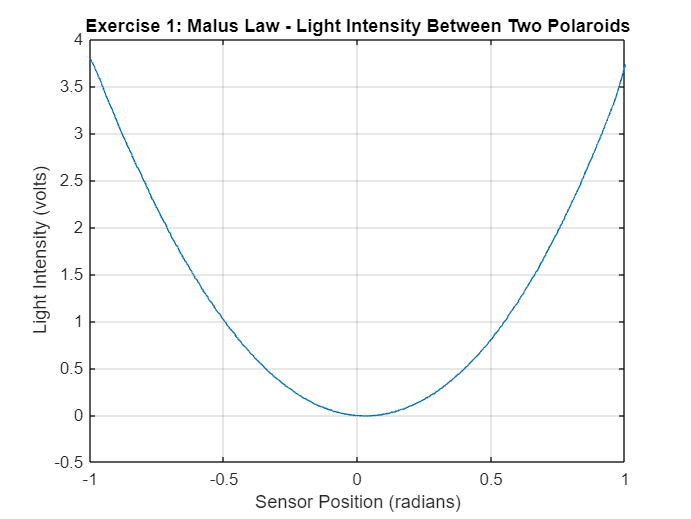


angle = table2array(data_1(:, "SensorPosition_Radians_"));
intensity = table2array(data_1(:, "LightIntensity_Volts_"));

% Line of Best Fit

x = cos(angle);
y = intensity;

yu = max(y);
yl = min(y);
yr = (yu-yl);
yz = y-yu+(yr/2);
zx = x(yz .* circshift(yz,[0 1]) <= 0);
per = 2*mean(diff(zx));
ym = mean(y);
fit = @(b,x)  b(1).*(sin(2*pi*x./b(2) + 2*pi/b(3))) + b(4);
fcn = @(b) sum((fit(b,x) - y).^2);
s = fminsearch(fcn, [yr;  per;  -1;  ym]);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: NaN 



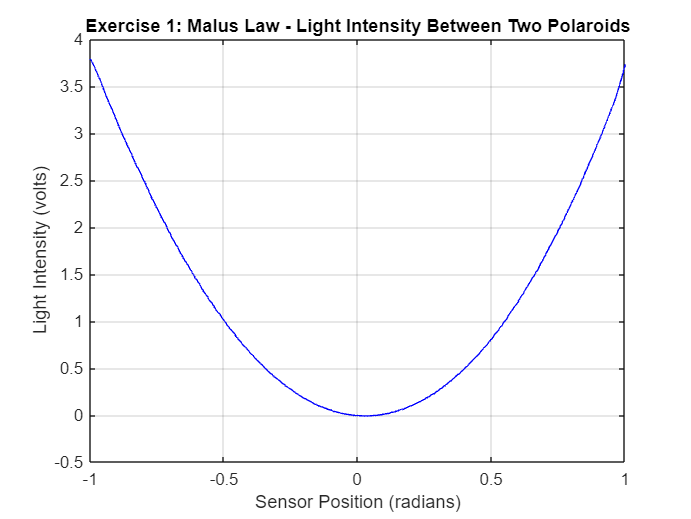

xp = linspace(min(x), max(x));

% s(1): sine wave amplitude (in units of y)
% s(2): period (in units of x)
% s(3): phase (phase is s(2)/(2*s(3)) in units of x)
% s(4): offset (in units of y)

plot(x, y, 'b', xp, fit(s, xp), 'r')
xlabel("Sensor Position (radians)");
ylabel("Light Intensity (volts)");
title("Exercise 1: Malus Law - Light Intensity Between Two Polaroids");
grid

% Residuals and Chi-Squared